% matlab 
clear;
clc

inputs = [[0.01:0.01:1];[0.01:0.01:1]];
targets = (inputs(1,:).^2+inputs(2,:).^2)/2 ; 

y=$x_1^2 + x_2^2/2$

 
% Create a Fitting Network: fitnet: mse
hiddenLayerSize = 20; 
net = fitnet(hiddenLayerSize);
 
% Train the Network
[net,tr] = train(net,inputs,targets);
 
% Test the Network
outputs = net(inputs);
errors = gsubtract(outputs,targets);
performance = perform(net,targets,outputs)

performance =      1.011357156735084e-10


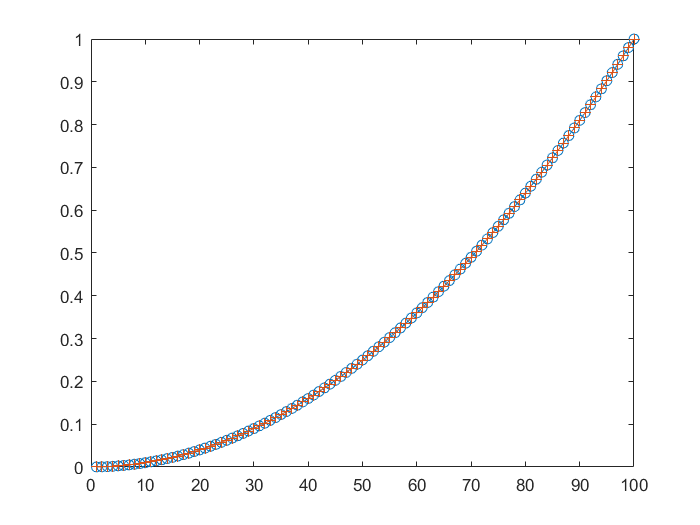

 
% View the Network
view(net)
figure, plot(targets,'o-'); hold on; plot(outputs,'+-.')